# Lesson III.4:   Continuous Linear Dynamics

Any extremely common model in applications is a ***linear system of differential equations*** which has the form

        (III.4.1)        $\dot{\bf x}=A{\bf x}$.

Here ${\bf x}$ is a vector-valued function (${\bf x}:{\mathbb R}\to{\mathbb R}^n$) of a scalar variable $t$, generally thought of as time, and the "dot" over ${\bf x}$ denotes the derivative with respect to $t$, i.e., $\dot{\bf x}=\frac{d \bf x}{dt}$.   The starting point, ${\bf x}(0)$, is generally given as well.   The solution of (III.4.1) is easily written in terms of the exponential of the matrix $A$:

        (III.4.2)        ${\bf x}(t)=e^{At} {\bf x}(0)$.

The proof of this formula for the solution of (III.4.1) is further discussed in Appendix III.4A.   To make sense of the exponential of a matrix, we recall that exponentials of numbers ($1\times 1$ matrices) can be defined in terms of powers of those numbers using power series.   This formulation is easily extended to general square matrices:

        (III.4.3)        $e^{At}=\sum_{k=0}^\infty \frac1{k!}t^kA^k$.

When $A$ is diagonalizable, the diagonalization $A=SDS^{-1}$can be used to analyze and simplify the exponential of a matrix.

        (III.4.4a)        $e^{At}=\sum_{k=0}^\infty \frac1{k!}t^kA^k=
\sum_{k=0}^\infty \frac1{k!}t^k(SDS^{-1})^k=
\sum_{k=0}^\infty \frac1{k!}t^kSD^kS^{-1}=
S\left(\sum_{k=0}^\infty \frac1{k!}t^k\left[\matrix{\lambda_1^k & &\cr &\ddots & \cr & & \lambda_n^k}\right]\right)S^{-1}$

        (III.4.4b)    $\qquad=
S\left(\sum_{k=0}^\infty \frac1{k!}t^k
\left[\matrix{\lambda_1^k & &\cr &\ddots & \cr & & \lambda_n^k}\right]
\right)S^{-1}
=S\left(\left[\matrix{\sum_{k=0}^\infty \frac1{k!}t^k\lambda_1^k & &\cr &\ddots & \cr & &\sum_{k=0}^\infty \frac1{k!}t^k \lambda_n^k}\right]\right)S^{-1}$

        (III.4.4c)    $\qquad=S\left[\matrix{e^{t\lambda_1} & &\cr &\ddots & \cr & & e^{t\lambda_n}}\right]S^{-1}$

        (III.4.4d)    $\qquad=Se^{Dt}S^{-1}$

**Example III.4.1:  **Consider the linear system (III.4.1) with $A=\left[\matrix{2 & 1 \cr 1 & 2}\right]=\left[\matrix{1 & 1 \cr 1 & -1}\right]
\left[\matrix{3 & 0 \cr 0 & 1}\right]
\left[\matrix{1&1\cr1&-1}\right]^{-1}=
\left[\matrix{1 & 1 \cr 1 & -1}\right]
\left[\matrix{3 & 0 \cr 0 & 1}\right]
\left[\matrix{\frac12&\frac12\cr\frac12&-\frac12}\right]$.   According to (III.4.2) and (III.4.4d),

                
$${\bf x}(t)~=~\frac12 \left[\matrix{1&1\cr  1 & -1}\right]
\left[\matrix{e^{3t} & 0 \cr 0 & e^t}\right]\left[\matrix{1&1\cr  1 & -1}\right]\left[\matrix{x_1(0)\cr x_2(0)}\right]~=~\frac12\left[\matrix{ 
\big( x_1(0)+x_2(0)\big)e^{3t}~+~\big(x_1(0)-x_2(0)\big)e^t \cr 
\big( x_1(0)+x_2(0)\big)e^{3t}~+~\big(x_1(0)-x_2(0)\big)e^t}\right].$$


**Example III.4.2: **Consider the linear system (III.4.1) with $A~=~\left[\matrix{1&-1\cr1 & 1}\right]~=~\frac12\left [ \matrix{-i & i\cr 1 & 1 }\right] \left[\matrix{1-i & 0 \cr 0 & 1+i}\right]\left[\matrix{i & 1 \cr -i & 1}\right]$.   According to (III.4.2) and (III.4.4d),

             
$${\bf x}(t)~=~\frac12\left [ \matrix{-i & i\cr 1 & 1 }\right] \left[\matrix{e^{(1-i)t} & 0 \cr 0 & e^{(1+i)t}}\right]\left[\matrix{i & 1 \cr -i & 1}\right]\left[\matrix{x_1(0)\cr x_2(0)}\right]=
\frac12e^t\left[\matrix{\big(x_1(0)+x_2(0)\big)e^{it}~+~\big(x_1(0)-x_2(0)\big)e^{-it}\cr -\big(x_1(0)-x_2(0)\big)e^{it}~+~\big(x_1(0)+x_2(0)\big) e^{-it}}\right]$$
   

                      $=~e^t\left[\matrix{ x_1(0)\cos t+x_2(0)\sin t \cr
-x_1(0)\sin t+ x_2(0)\cos t}\right]$.

### **General damped spring-mass oscillator.  **

The damped spring-mass oscillator is governed by the second-order differential equation

        (III.4.5)        $m\ddot y+\mu \dot y + ky = 0$

where the mass $m$, the friction constant $\mu$ and the spring constant $k$ are nonnegative constants.   Supplemented with the equation $u=\dot y$, this system may be written as first-order linear system:

        (III.4.6)        $\left\{\matrix{\dot u &=&-\frac{\mu}{m} u-\frac{k}{m} y \cr \dot y&=&u\qquad\quad}\qquad\qquad\Rightarrow\qquad\qquad
\left[\matrix{\dot u\cr \dot y}\right]=\left[\matrix{-\frac{\mu}{m}& -\frac{k}{m} \cr 1 & 0 }\right]\left[\matrix{u\cr y}\right]$.

The eigenvalues are

        (III.4.7)        $\lambda_\pm = \frac{-\mu\pm\sqrt{\mu^2-4km}}{2m}$.

There are three cases of physical significance:

**Overdamped oscillator** ($\mu^2-4km>0$).   The eigenvalues are both negative real numbers.   Hence, solutions decay exponentially to rest.

        (III.4.8a)        $y(t)=C_+ e^{\lambda_+ \,t} + C_-e^{\lambda_-\, t}$

**Example III.4.3:  **Consider $\ddot y+5\dot y +6 y =0$ with initial conditions $y(0)=y_0$ and $\dot y(0)=u_0$.  Letting $u=\dot y$, this second-order equation may be reformulated as a first-order system

                $\left[\matrix{\dot u\cr \dot y}\right]~=~A \left[\matrix{u\cr y}\right] \quad\text{where}\quad
A=\left[\matrix{-5 & -6\cr 1 & 0 }\right]\quad\text{and}\quad \left[\matrix{u(0)\cr y(0)}\right]=\left[\matrix{u_0\cr y_0}\right]$.

        
$$p_A(\lambda)=\lambda^2+5\lambda+6=(\lambda+2)(\lambda+3)$$


            
$$\underline{\lambda_1=-2}:\qquad A-\lambda_1 I=\left[\matrix{-3 & -6 \cr 1 & 2}\right]\quad\Rightarrow\quad {\bf v}_1=\left[\matrix{2\cr -1}\right]
$$


            
$$\underline{\lambda_2=-3}:\qquad A-\lambda_2 I=\left[\matrix{-2 & -6 \cr 1 & 3}\right]\quad\Rightarrow\quad {\bf v}_2=\left[\matrix{3\cr -1}\right]
$$


        $\left[\matrix{ u(t)\cr y(t)}\right]~=~
\left[\matrix{2&3\cr -1 & -1}\right]
\left[\matrix{e^{-2t} & 0 \cr 0 & e^{-3t}}\right]
\left[\matrix{2 & 3 \cr -1 & -1 }\right]^{-1}
\left[\matrix{u_0\cr y_0}\right]~=~
\left[\matrix{
(3u_0+6y_0)e^{-3t}~+~ (-2u_0-6y_0)e^{-2t} \cr
(-u_0-2y_0)e^{-3t}~+~ (u_0+3y_0)e^{-2t}}\right]$.

       Plots of solutions for various initial conditions (forward phase curves):

A=[-5 -6; 1 0];
theta=0:pi/25:2*pi;
x0=[cos(theta); sin(theta)];       % a range of initial conditions on a circle
dt=0.01;                           % time interval for plotting
Max=200;                           % maximum number of time steps
desolveplot(A,x0,dt,Max)

Note that the set of initial conditions for which the mass settles into the equilibrium without passing through it.   For other initial conditions the mass passes through the equilibrium exactly once before settling.

**Underdamped oscillator** ($\mu^2-4km<0$).   The eigenvalues are a complex conjugate pair with a negative real part $\lambda_\pm=-\alpha\pm i\omega\quad(\alpha>0,~\omega>0)$.   Hence, solutions decay but with oscillations.

        (III.4.8b)        $y(t)=e^{-\alpha t} \big( C_1 \cos(\omega t) + C_2\sin(\omega t)\big)$

since $e^{\lambda_\pm t}=e^{-\alpha t}e^{\pm\omega t}=e^{-\alpha t} \big(\cos(\omega t)\pm i\sin(\omega t)\big)$

**Example III.4.4:  **Consider $\ddot y+4\dot y +5 y =0$ with initial conditions $y(0)=y_0$ and $\dot y(0)=u_0$.  Letting $u=\dot y$, this second-order equation may be reformulated as a first-order system

                $\left[\matrix{\dot u\cr \dot y}\right]~=~A \left[\matrix{u\cr y}\right] \quad\text{where}\quad
A=\left[\matrix{-4 & -5\cr 1 & 0 }\right]\quad\text{and}\quad \left[\matrix{u(0)\cr y(0)}\right]=\left[\matrix{u_0\cr y_0}\right]$.

        
$$p_A(\lambda)=\lambda^2+4\lambda+5 \qquad \lambda_\pm=\frac{-4\pm\sqrt{16-20}}{2}=-2\pm i$$


            
$$\underline{\lambda_\pm=-2\pm i}:\qquad A-\lambda_\pm I = \left[\matrix{-2\mp i & -5 \cr 1 & 2\mp i}\right]\quad\Rightarrow\quad {\bf v}_\pm=\left[\matrix{-2\pm i\cr 1}\right]
$$


        $\matrix{
\left[\matrix{ u(t)\cr y(t)}\right]~&=&~
\left[\matrix{-2+i&-2-i\cr 1 & 1} \right]
\left[\matrix{e^{(-2+i)t} & 0 \cr 0 & e^{(-2-i)t}}\right]
\left[\matrix{-2+i&-2-i\cr 1 & 1}\right]^{-1}
\left[\matrix{u_0\cr y_0}\right] \cr
&=&~\left[\matrix{e^{(-2+i)t} \left(u_0\frac12i+y_0 \frac52 i\right)~+~ e^{(-2-i)t}\left(u_0(\frac12+i)-y_0\frac52 i\right) \cr 
e^{(-2+i)t} \left(-u_0\frac12 i+ y_0(\frac12-i)\right)+e^{(-2-i)t} \left(u_0\frac12 i+ y_0(\frac12+i)\right)
}\right]\cr
~&=&~ e^{-\alpha t}\left[
\matrix{
(u_0+\alpha y_0-u_0\alpha) \cos(\omega t)-(u_0\omega+\frac{\alpha}{\omega} u_0+ \frac{\alpha^2}{\omega} y_0) \sin(\omega t) \cr
u_0  \cos(\omega t) + \big( \frac{u_0}{\omega} +\frac{\alpha y_0}{\omega}\big)  \sin(\omega t)
}\right]
}$.

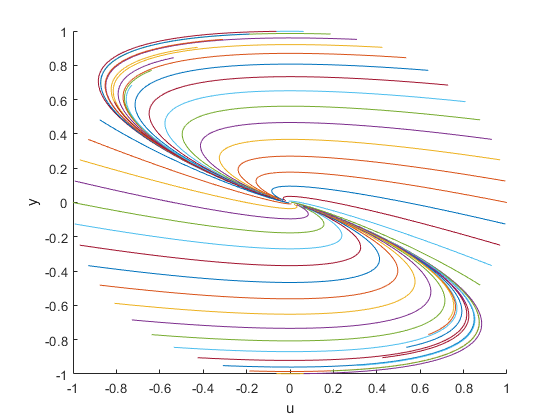

A=[-4 -5; 1 0];
theta=0:pi/25:2*pi;
x0=[cos(theta); sin(theta)];       % a range of initial conditions on a circle
dt=0.01;                           % time interval for plotting
Max=200;                           % maximum number of time steps
desolveplot(A,x0,dt,Max)

Despite similarities with the phase diagram of the previous example, close inspection reveals that all nonequilibrium initial condition result in the mass passing through the equilibrium infinitely many times.

**Critically damped** ($\mu^2-4km=0$).   In the critically damped case, there is only one independent eigenvector; so the matrix is defective.    We can, however, find a generalized eigenvector that works almost as well.

        (III.4.8c)          $\lambda=-\frac{\mu}{2m}$:        $A-\lambda I=\left[\matrix{-\frac{\mu}{2m} & -\frac{k}{m} \cr 1 & \frac{\mu}{2m} }\right]=\left[\matrix{-\frac{\mu}{2m} & -\frac{\mu^2}{4m^2}\cr 1 & \frac{\mu}{2m} }\right]\qquad\Rightarrow\qquad {\bf v}=\left[\matrix{\mu\cr -2m}\right]$

The generalized eigenvector ${\bf w}$ is selected such that $(A-\lambda I){\bf w}={\bf v}$.  A good choice is${\bf w}=\left[\matrix{-2m\cr 0}\right]$ with the result that $A{\bf w}={\bf v}+\lambda{\bf w}$.  Hence,

        (III.4.9)        $A\left[\matrix{{\bf v} & {\bf w}}\right]=\left[\matrix{A{\bf v} & A{\bf w}}\right]=\left[\matrix{\lambda{\bf v} & {\bf v}+\lambda{\bf w}}\right]=\left[\matrix{{\bf v} & {\bf w}}\right]\left[\matrix{\lambda & 1 \cr 0 & \lambda}\right]

$

Multiplying on the right by $\left[\matrix{{\bf v} & {\bf w}}\right]^{-1}$

        (III.4.10)        $A=\left[\matrix{{\bf v} & {\bf w}}\right]\left[\matrix{\lambda & 1 \cr 0 & \lambda}\right]\left[\matrix{{\bf v} & {\bf w}}\right]^{-1}$.

This is not quite diagonalization; however, we do have the formula

        (III.4.11)        $A^p=\left[\matrix{{\bf v} & {\bf w}}\right]\left[\matrix{\lambda & 1 \cr 0 & \lambda}\right]^p\left[\matrix{{\bf v} & {\bf w}}\right]^{-1}$.

From the result,

        (III.4.12)        $\left[\matrix{\lambda & 1 \cr 0 & \lambda}\right]^p=\left[\matrix{\lambda^p & p\lambda^{p-1} \cr 0 & \lambda^p}\right]$

and the calculation

        (III.4.13)        $\sum_{\ell=0}^\infty \frac{1}{\ell!} \ell 
\lambda^{\ell-1}t^\ell=\sum_{\ell=1}^\infty \frac{1}{\ell!} \ell 
\lambda^{\ell-1}t^\ell=t\sum_{\ell=1}^\infty \frac{1}{(\ell-1)!}
\lambda^{\ell-1}t^{\ell-1}=t\sum_{m=0}\frac{1}{m!}\lambda^mt^m=te^{\lambda t}$

it follows that

        (III.4.14)        $y(t)=C_1 e^{-\frac{\mu}{2m}t}~+~C_2te^{-\frac{\mu}{2m}t}$.

**Example III.4.4:  **Consider $\ddot y+4\dot y +4 y =0$ with initial conditions $y(0)=y_0$ and $\dot y(0)=u_0$.  Letting $u=\dot y$, this second-order equation may be reformulated as a first-order system

                $\left[\matrix{\dot u\cr \dot y}\right]~=~A \left[\matrix{u\cr y}\right] \quad\text{where}\quad
A=\left[\matrix{-4 & -4\cr 1 & 0 }\right]\quad\text{and}\quad \left[\matrix{u(0)\cr y(0)}\right]=\left[\matrix{u_0\cr y_0}\right]$.

                
$$\left[\matrix{u(t)\cr y(t)}\right]=e^{At} \left[\matrix{u_0\cr y_0}\right]=e^{-2t} \left[\matrix{1-2t & -4t\cr t & 2t+1}\right] \left[\matrix{u_0\cr y_0}\right]$$


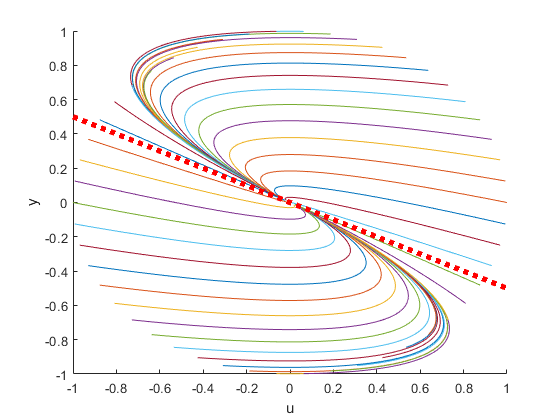

A=[-4 -4; 1 0];
theta=0:pi/25:2*pi;
x0=[cos(theta); sin(theta)];       % a range of initial conditions on a circle
dt=0.01;                           % time interval for plotting
Max=200;                           % maximum number of time steps
desolveplot(A,x0,dt,Max)

In the critically damped case, the two eigendirections have pinched together into a single direction.

### **Rotation as an exponential of an antisymmetric matrix.    **

A $n\times n$ real matrix $A$ is antisymmetric (or skew-symmetric) if $A^T =-A$.    A few examples,

        $\left[\matrix{0  & 2\cr -2 & 0}\right],\qquad\qquad
\left[\matrix{0&1&-2&3\cr-1&0&-4&5\cr -2&4&0&-6\cr-3&-5&6&0}\right],
\qquad\qquad
\left[\matrix{0 & a& b\cr -a & 0 & c\cr -b&-c&0}\right],\qquad\qquad\left[\matrix{0&0&0\cr0&0&0\cr0&0&0}\right]$.

A particularly notable property is that if $A$ is antisymmetric then $U=e^A$ is orthogonal:

        (III.4.15a)        $U^TU=\big(e^A\big)^Te^A=e^{A^T}e^A=e^{-A}e^{A}=e^{-A+A}=e^O=I$.

Moreover, 

        (III.4.15b)        $\det(U)=\det(e^{A})=1$.

In the case of a $2\times 2$ antisymmetric matrix, we have

        (III.4.16)        $\exp\left(\left[\matrix{0&a\cr-a&0}\right]\right)=\left[\matrix{\cos a & \sin a\cr -\sin a & \cos a}\right]$

as MATLAB verifies:

a=sym('a')

$$a = a$$

A=[0 a; -a 0]

$$A = \left(\begin{array}{cc} 0 & a\\ -a & 0 \end{array}\right)$$

[S,D]=eig(A)

$$S = \left(\begin{array}{cc} \mathrm{i} & -\mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} -a\,\mathrm{i} & 0\\ 0 & a\,\mathrm{i} \end{array}\right)$$

expm(A)

$$ans = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{-a\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{a\,\mathrm{i}}}{2} & \frac{{\mathrm{e}}^{-a\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{a\,\mathrm{i}}\,\mathrm{i}}{2}\\ -\frac{{\mathrm{e}}^{-a\,\mathrm{i}}\,\mathrm{i}}{2}+\frac{{\mathrm{e}}^{a\,\mathrm{i}}\,\mathrm{i}}{2} & \frac{{\mathrm{e}}^{-a\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{a\,\mathrm{i}}}{2} \end{array}\right)$$

For the $3\times 3$ antisymmetric matrix $A=\left[\matrix{0&a&b\cr-a&0&c\cr-b&-c&0}\right]$ diagonalization is somewhat more complicated:

    
$$\left|\matrix{0 & a & b \cr -a & 0 & c \cr -b & -c & 0}\right|=0\left|\matrix{0&c\cr-c&0}\right|-a\left|\matrix{-a&c\cr -b & 0}\right|+b\left|\matrix{-a&0\cr-b&-c}\right|=0-abc+abc=0$$


    
$$p_A(\lambda)=-\lambda^3+(0+0+0)\lambda^2-\left( \left|\matrix{0 & a\cr -a & 0 }\right|+\left|\matrix{0 & b\cr-b&0}\right|+\left|\matrix{0&c\cr -c & 0 }\right|\right)\lambda=-\lambda^3-(a^2+b^2+c^2)\lambda=-\lambda(\lambda+i\theta)(\lambda-i\theta)$$


where $\theta^2=a^2+b^2+c^2$; that is, $\lambda_1=0,\lambda_2=i\theta,\lambda_3=-i\theta.$


$$\underline{\lambda_1=0}:\qquad A-\lambda_1 I =\left[\matrix{0&a&b\cr-a&0&c\cr-b&-c&0}\right] \sim \left[\matrix{0&a&b \cr -a & 0 & c \cr 0 & 0 & 0 }\right]\qquad\Rightarrow\qquad{\bf v}_1=\left[\matrix{c\cr -b\cr a}\right]$$


To continue this example, we assume for the sake of simplicity and clarity $a=0,~b=-1,~\text{and}~c=1$.   Moreover, we do not seek the remaining eigenvectors which will be complex.   Rather we recognize that ${\bf v}_1$ is the axis of rotation and choose ${\bf v}_2$ and ${\bf v}_3$ to be an orthonormal basis for the plane of rotation which is the two-dimensional subspace orthogonal to ${\bf v}_1$.   Finally, we normalize ${\bf v}_1$so that $\{{\bf v}_1,{\bf v}_2,{\bf v}_3\}$forms an orthonormal basis for ${\mathbb R}^3$.    For this special case:

        $A=\left[\matrix{0&0&-1\cr0&0&1\cr1&-1&0}\right],\qquad\lambda_1=0,\quad\lambda_{2,3}=\pm i\theta=\pm i \sqrt{2}
\qquad\text{and}\qquad
\left[\matrix{{\bf v}_1 & {\bf v}_2 & {\bf v}_3}\right]=\left[\matrix{\theta/2 & \theta/2 & 0 \cr \theta/2 & -\theta/2 & 0 \cr 0 &0&1}\right]$.

Hence,

        
$$A\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]=
\left[\matrix{0&0&-1\cr 0 &0&1\cr1&-1&0}\right]\left[\matrix{\theta/2 &\theta/2 &0\cr\theta/2&-\theta/2&0\cr0&0&1}\right]=\left[\matrix{0 &0 & -1\cr 0&0&1\cr0&\theta&0 }\right]=\left[\matrix{\lambda_1 {\bf v}_1 & \theta{\bf v}_3&-\theta{\bf v}_2}\right]=\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]\left[\matrix{\lambda_1 & 0 & 0 \cr 0&0 &-\theta\cr0&\theta & 0}\right]$$


Hence, we have a partial diagonalization

        (III.4.7)        $A=\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]\left[\matrix{\lambda_1 & 0 & 0 \cr 0&0 &-\theta\cr0&\theta & 0}\right]\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]^T$

Here, we have made use of the orthonormal basis $\{{\bf v}_1,{\bf v}_2,{\bf v}_3\}$ to recognize that $\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]$is an orthogonal matrix so that

$\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]^{-1}=\left[\matrix{{\bf v}_1&{\bf v}_2&{\bf v}_3}\right]^T.$  This result foreshadows the many benefits of using an orthonormal basis--particularly an orthonormal eigenbasis as is studied in the next lesson.   From (III.4.7) a useful formula for the rotation matrix $U=e^{At}$ follows:

        $e^{At}=\left[\matrix{\sigma &\sigma &0\cr\sigma&-\sigma&0\cr0&0&1}\right]
\left[\matrix{1&0&0\cr 0 & \cos(\sigma t) & -\sin(\sigma t) \cr 0 &\sin(\sigma t) & \cos(\sigma t)}\right]
\left[\matrix{\sigma &\sigma &0\cr\sigma&-\sigma&0\cr0&0&1}\right]$.

Such matrices can be used to manipulate objects in three dimensions.

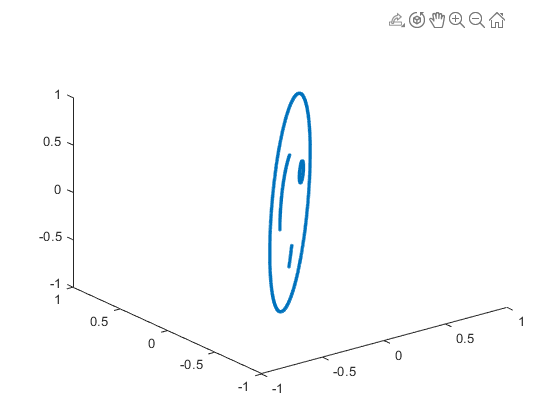

A=[0 0 -1; 0 0 1; 1 -1 0];
rollface(A)

**Appendix III.4A:   Exponential solution of a homogeneous first-order system of linear differential equations.   **Supposing that

        (III.4A.1)    $e^{At}=\sum_{\ell=0}^\infty \frac{t^n}{\ell!} A^\ell$

we note that taking the derivative term-by-term yields

        (III.4A.2)    $\frac{d}{dt} \left(\sum_{\ell=0}^\infty \frac{t^\ell}{\ell!}A^\ell \right)
=\sum_{\ell=1}^\infty \frac{\ell t^{\ell-1}}{\ell!}A^\ell
=A\left(\sum_{\ell=1}^\infty \frac{ t^{\ell-1}}{(\ell-1)!}A^{\ell-1}\right)
=\left(\sum_{\ell=0}^\infty \frac{ t^\ell}{\ell!}A^{\ell}\right)A=Ae^{At}$ .

From this result, $\frac{d}{dt}e^{At}=Ae^{At}$, it follows that (III.4.2) indeed gives the solution of (III.4.1).   We have, however, neglected to demonstrate the convergence of (III.4A.1) and (III.4A.2).   Here we simply summarize the fundamental theorem that validates this computation:   Suppose the power series $\sum_{\ell=0}^\infty a_\ell z^\ell$ converges for $|z|<R$ then the matrix power series $\sum_{\ell=0}^\infty a_\ell t^n A^n$

- converges as long as $|t\lambda_\ell|<R$ for $\ell=1,\dots,n,$

- may be validly differentiated term-by-term under the same conditions.

The power series for the exponential function converges for all values of $z$, that is, the radius of convergence is $R=\infty$.

**Appendix III.4B:   Properties of the matrix exponential.   **First the obvious:   If $O$ is a square zero matrix, 

        (III.4B.1)        $e^O=I$.

Less obvious:   If $A$ and $B$ commute then

        (III.4B.2)        $e^{A+B}=e^A e^B$.

The proof depends on the binomial theorem

        (III.4B.3)        $(A+B)^\ell=\sum_{j=0}^\ell \frac{\ell!}{(\ell-j)! j!} A^{\ell-j}B^j$

which requires that $A$ and $B$ commute.

             
$$\matrix{
\text{(III.2B.4a)}&\qquad&e^{A+B}&=&\sum_{\ell=0}^\infty \frac{1}{\ell!} (A+B)^\ell\qquad\qquad\quad \cr
\text{(III.2B.4b)}&\qquad&&=& \sum_{\ell=0}^\infty \frac{1}{\ell!} \sum_{j=0}^\ell \frac{\ell!}{(\ell-j)! j!} A^{\ell-j}B^j \cr
\text{(III.2B.4c)}&\qquad&&=& \sum_{\ell=0}^\infty \sum_{j=0}^\ell \frac{1}{(\ell-j)!j!} A^{\ell-j}B^j \quad\cr
\text{(III.2B.4d)}&\qquad&&=& \sum_{j=0}^\infty \sum_{\ell=j}^\infty \frac{1}{(\ell-j)!j!}A^{\ell-j}B^j \quad \cr
\text{(III.2B.4e)}&\qquad&&=& \sum_{j=0}^\infty \frac{1}{j!}B^j \sum_{\ell=j}^\infty \frac{1}{(\ell-j)!}A^{\ell-j}\quad\cr
\text{(III.2B.4f)}&\qquad&&=& \sum_{j=0}^\infty \frac{1}{j!}B^j \sum_{m=0}^\infty \frac{1}{m!}A^m\qquad\qquad\cr
\text{(III.2B.4g)}&\qquad&&=& e^{B} e^{A}\qquad\qquad\qquad\qquad\qquad\cr
}$$


**Follow-up Problems**:

**Problem III.4.1:   **Find $y(t)$ such that 

                $\left\{\qquad\matrix{\ddot y &-& y&=&0\cr
&&y(0)&=&1\cr
&&\dot y(0)&=&0\cr
}$.

**Problem III.4.2:   **Find $y(t)$ such that 

                $\left\{\qquad \matrix{\ddot y~-~2\dot y &+& y&=&0\cr
&&y(0)&=&1\cr
&&\dot y(0)&=&0\cr
}$.

**Problem III.4.3:  **Assuming $y(0)\ne 0$ what is the maximum number of roots for $y(t)$ given by (III.4.8a)?

**Problem III.4.4:**   Given $y(0)=1$ and $\dot y(0)=2$ find $C_+$ and $C_-$ in equation (III.4.8a).

**Problem III.4.5:   **Suppose ${\bf x}(t)$ is given by (III.4.2).   Find the matrix $M$such that ${\bf x}(t+\Delta t)=M{\bf x}(t)$.

**Problem III.4.6:**   A collection of $N$identical spheres with mass $m$ are connected by identical Hookean springs having spring constants $k$ and inserted into a frictionless, airless circular tube have a radius equal to the radius of the spheres.   The first and last spheres are connected by springs to the endcaps of the tube.   Write the first-order system of equations, in matrix form, describing this system in terms of the displacements and velocities of the spheres from their equilibrium positions.

**Problem III.4.7:   **Why is $\exp(A)$ always invertible?

**Problem III.4.8:   **Suppose $A$ is an $n\times n$ antisymmetric matrix ($A^T=-A$).     

    (a)   Show that ${\bf x}^T A {\bf x}=0$ for all ${\bf x}\in{\mathbb R}^n$.

    (b)   If $\dot {\bf x}=A{\bf x}$, show that $\frac{d}{dt} ||{\bf x}(t)||^2=0$.

**Problem III.4.9:   **Logarithms of $2\times 2$ orthogonal matrices.

    (a)    For the rotation matrix $U=\left[\matrix{\cos\theta & -\sin\theta\cr \sin\theta &\cos\theta}\right]$, find a matrix $B$ such that $U=e^B$.

    (b)*  For the reflection matrix $U=\left[\matrix{\cos 2\theta & \sin 2\theta\cr \sin 2\theta & -\cos 2\theta}\right]$, find a matrix $B$ such that $U=e^B$.

**Problem III.4.10:**  Verify that $U=\left[\matrix{\cos^2\theta & -\sin\theta & -\sin\theta\cos\theta\cr \sin\theta\cos\theta & \cos\theta &-\sin^2\theta\cr \sin\theta & 0 & \cos\theta}\right]$ is a rotation matrix (orthogonal matrix with positive determinant).   *What is the axis of rotation of $U$?

function desolveplot(A,x0,dt,Cmax)
    clf
    L=1;
    axis([-L L -L L])
    xlabel('u')
    ylabel('y')
    hold on
    E=expm(A*dt);
    for x=x0
        clearvars xp
        for c=1:Cmax
            xp(:,c)=x;
            x=E*x;
        end
        plot(xp(1,:),xp(2,:))
    end
    % eigendirections
    [S,D]=eig(A);
    if isreal(S)
        f1=max(abs(S(1,1)), abs(S(2,1)) );
        plot( [ S(1,1)/f1 -S(1,1)/f1 ] , [ S(2,1)/f1 -S(2,1)/f1 ], ':r','LineWidth',4)
        f2=max(abs(S(1,2)), abs(S(2,2)) );
        plot( [ S(1,2)/f2 -S(1,2)/f2 ] , [ S(2,2)/f2 -S(2,2)/f2 ], ':r','LineWidth',4);
    end
end


function FACE = face3D()
    theta=0.0:0.01:2*pi; 
    outline = [ cos(theta); sin(theta); 0.0*theta];                     % outline of face 
    leye    = [0.4+0.1*cos(theta);0.4+0.1*sin(theta); 0.0*theta];       % left eye
    reye    = [-0.5:0.01:-0.3; 0.4*(1+0*(-0.5:0.01:-0.3)); 0.0*(-0.5:0.01:-0.3)];  % right eye
    theta   = 5*pi/4:0.01:7*pi/4;
    smile   = [0.5*cos(theta); 0.5*sin(theta); 0.0*theta];              % smile
    FACE    = [outline leye reye smile];                                % face assembled
end

function rollface(A)
figure
    FACE = face3D();
    for t=0.0:0.02:10.0
        F=expm(t*A)*FACE;
        plot3(F(1,:),F(2,:),F(3,:),'.')
        axis([-1 1 -1 1 -1 1])
        pause(0.1);
    end
end